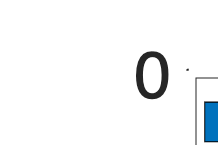

% Initialize arrays
first_latest = zeros(15, 8); % 15 years (2008-2022), 8 categories (4 for the start, 4 for the end)

for vc = 1:size(data)

    firstIndex = 1;
    while isnan(data{vc,10}(firstIndex).ObjcSwiftCloc.Swift.percentage) && isnan(data{vc,10}(firstIndex).ObjcSwiftCloc.Objective_C.percentage)
        firstIndex = firstIndex + 1;
    end
    i = year(data{vc, 10}(firstIndex).dateTime) - 2007; % Year of the first commit

    if data{vc,10}(end).ObjcSwiftCloc.Swift.percentage >= 98
        first_latest(i, 1) = first_latest(i, 1) + 1;
    elseif data{vc,10}(end).ObjcSwiftCloc.Swift.percentage > data{vc, 10}(end).ObjcSwiftCloc.Objective_C.percentage
        first_latest(i, 2) = first_latest(i, 2) + 1;
    elseif data{vc,10}(end).ObjcSwiftCloc.Objective_C.percentage >= 98
        first_latest(i, 4) = first_latest(i, 4) + 1;
    else
        first_latest(i, 3) = first_latest(i, 3) + 1;
    end
    

end

fig = figure;

fig.Position = [100, 100, 1200, 800]; % Width: 1200, Height: 600

% Create the bar chart
b = bar([2008:2022], first_latest, 'stacked');
b(1).FaceColor = "#D95319";
b(2).FaceColor = "#F3CBBA";
b(3).FaceColor = "#B2D4EB";
b(4).FaceColor = "#0072BD";

% Set the font size for the legend, axes labels and ticks
lgd = legend("Swift only", "Prevalence of Swift", "Prevalence of Objective-C", "Objective-C only", 'Location', 'northwest');
set(lgd, 'FontSize', 30);
xlabel("Year of the first commit", 'FontSize', 30);
ylabel("Number of apps", 'FontSize', 30);
set(gca, 'FontSize', 30);

% Adjust figure's paper size and position to match its content
set(gcf, 'PaperPositionMode', 'auto');
set(gcf, 'PaperUnits', 'points');
set(gcf, 'PaperSize', [1200 800]);
set(gcf, 'PaperPosition', [0 0 1200 800]);

% Save the figure as a cropped PDF
print(gcf, 'lang-first-latest-commit', '-dpdf', '-r0');